%mydata = load('RSdata_Kalman.mat')

%ms = mydata.rt_motor_speeds.signals.values;

% u = mydata.rt_optical_flow.signals.values(:,1);
% v = mydata.rt_optical_flow.signals.values(:,2);
% w = mydata.rt_optical_flow.signals.values(:,3);
u = mydata.rt_u.signals.values;
v = mydata.rt_v.signals.values;
w = mydata.rt_w.signals.values;
a_x = mydata.rt_a_x.signals.values;
a_y = mydata.rt_a_y.signals.values;
a_z = mydata.rt_a_z.signals.values;
p = mydata.rt_p.signals.values;
q = mydata.rt_q.signals.values;
r = mydata.rt_r.signals.values;
p_0 = mydata.rt_pressure.signals.values;
z_us = mydata.rt_z_ultrasonic.signals.values;

all_data = [u, v, w, a_x, a_y, a_z, p, q, r, p_0, z_us];
noise = zeros(size(all_data,1),size(all_data,2));
labels = ["u", "v", "w", "a_x", "a_y", "a_z", "p", "q", "r", "p_0","z_us"];

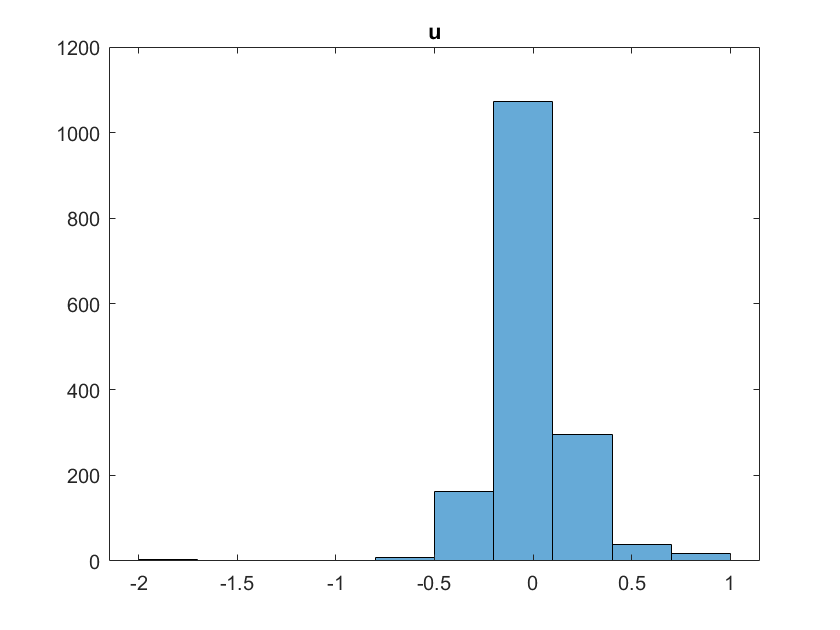

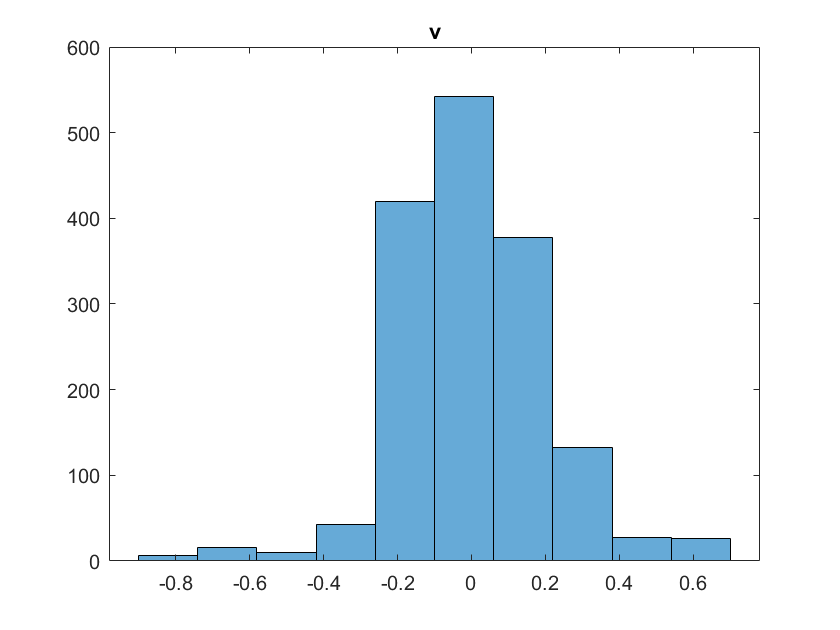

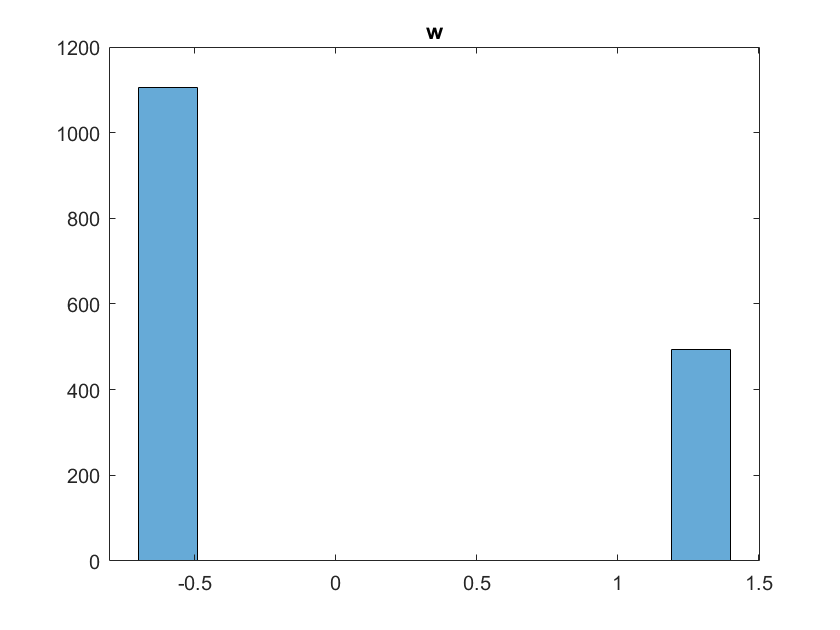

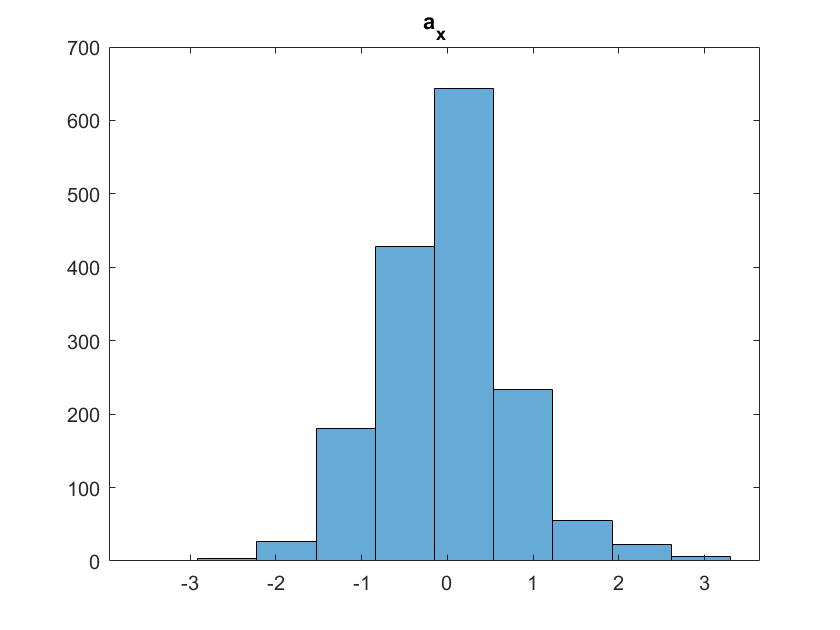

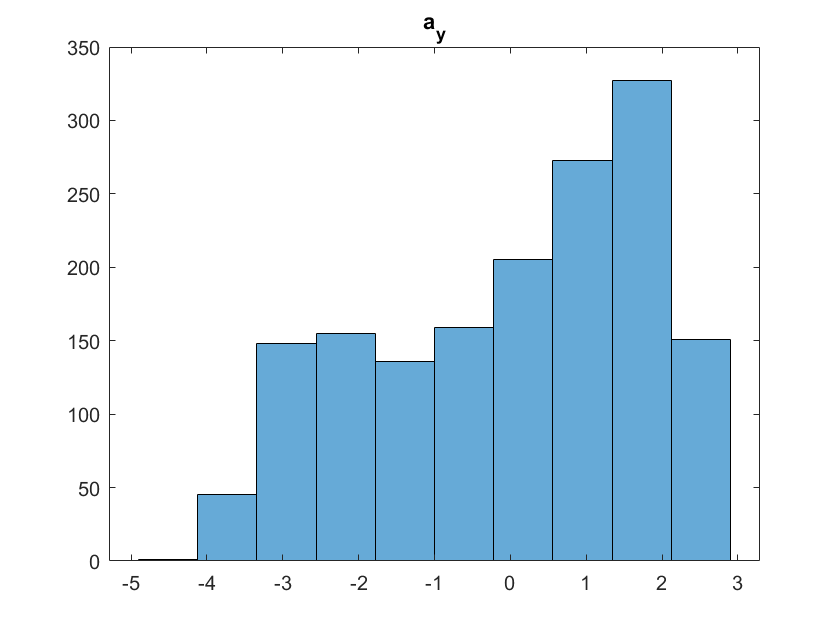

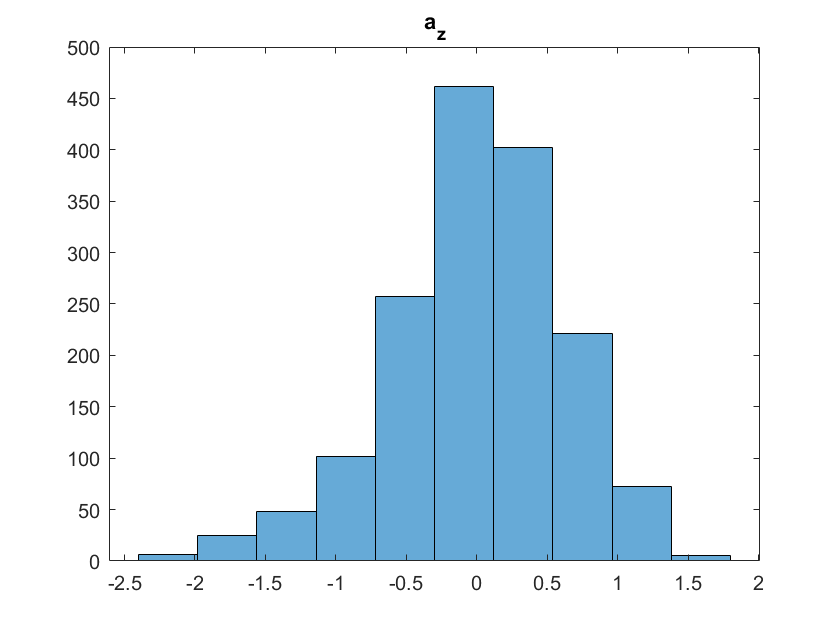

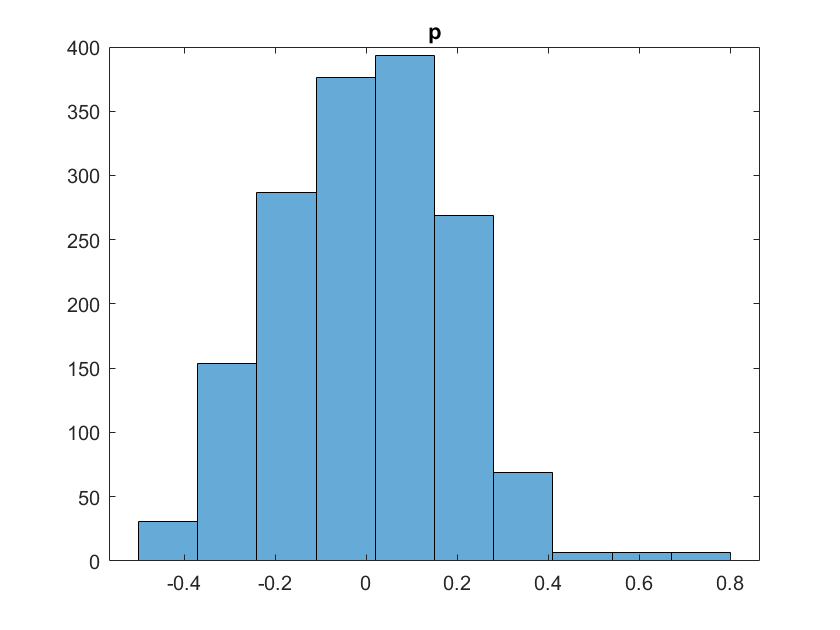

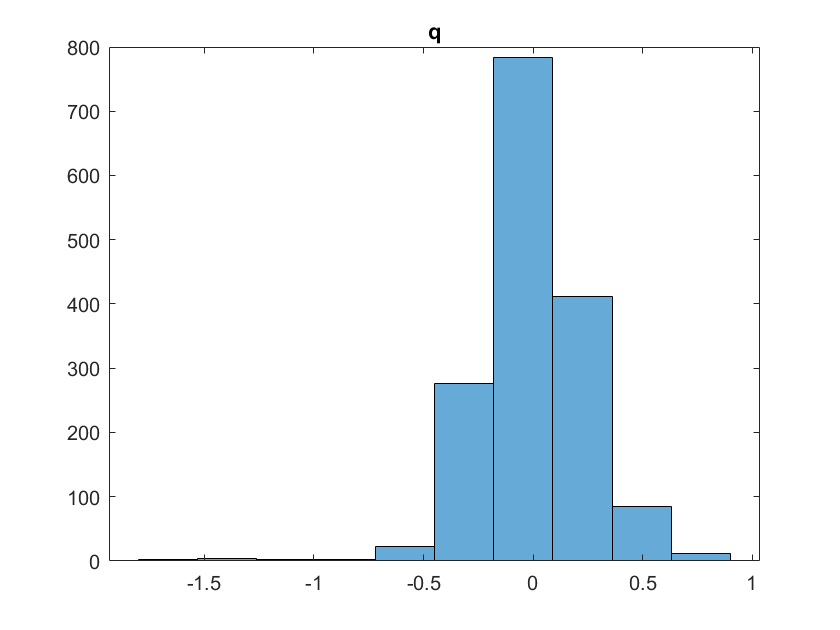

means = zeros(1,size(all_data,2));

for i=1:size(all_data,2)
    means(i) = mean(all_data(:,i));
    noise(:,i) = all_data(:,i) - means(i);
    figure;
    histogram(noise(:,i),10)
    title(labels(i))
end


covariances = cov(noise);

for i=1:size(all_data,2)
    fprintf('Variance of %s is %f \n',labels(i),covariances(i,i));
end

Variance of u is 0.053993 
Variance of v is 0.040670 
Variance of w is 0.854228 
Variance of a_x is 0.603879 
Variance of a_y is 3.186179 
Variance of a_z is 0.383473 
Variance of p is 0.037155 
Variance of q is 0.058542 
Variance of r is 0.038126 
Variance of p_0 is 10.438122 
Variance of z_us is 0.006783 



g = 9.8; % acceleration due to gravity m/s^2
M_air = 0.0289644; % molar mass of air in kg/mol
R = 8.31432; % universal gas constant Nm/mol/k
p0 = 101325 % Pa standard pressure

p0 = 101325

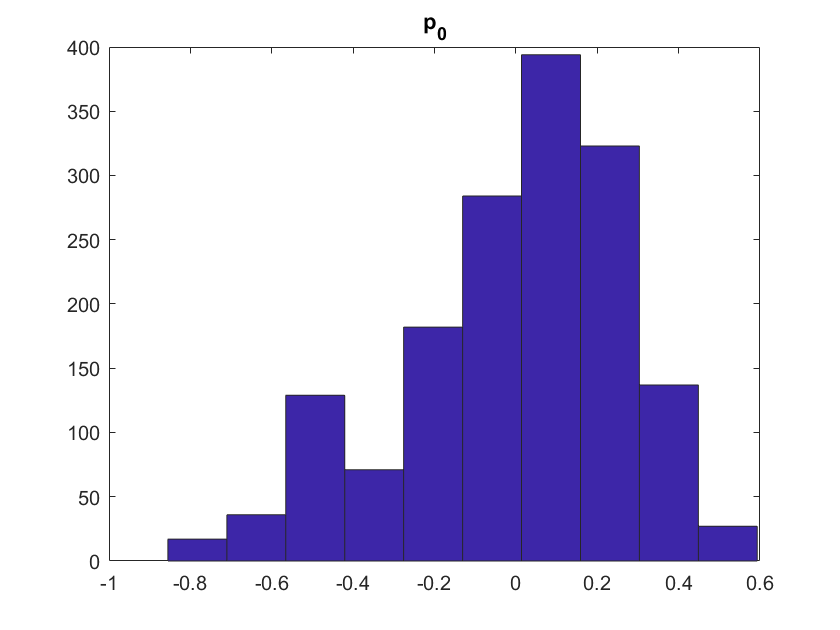

T_kelvin =288.15;  % Assumed temperature in kelvin
K =-g*M_air/R/T_kelvin;
dt = 1/200;
Kappa = 1;


z_hypsometric =@(P) 1/K.*log(P./p0);
p_0_mean = mean(p_0);
difference = z_hypsometric(p_0) - z_hypsometric(p_0_mean);
p_cov = cov(difference); %p_0
hist(difference)
title("p_0")


for i = 1:10
    for j = i:10
        correlation = corr(all_data(:,i),all_data(:,j));
        if abs(correlation) > 0.3 && (i ~= j)
            fprintf('Correlation between %s and %s is %f \n',labels(i),labels(j),corr(all_data(:,i),all_data(:,j)))
        end
    end
end

Correlation between u and a_x is -0.321772 
Correlation between v and p is -0.689924 
Correlation between a_y and a_z is 0.611041 
Correlation between a_y and p_0 is -0.750140 
Correlation between a_z and p_0 is -0.530078 


corr_matrix = corrcoef(all_data);



[A_t_dis,B_t_dis,C_t_dis,D_t_dis] = discretize(A_throttle,[0;1],[1 0],0,dt);
[A_e_dis,B_e_dis,C_e_dis,D_e_dis] = discretize(A_aileron(1:2,1:2),[0;1],eye(2),0,dt); 
[A_a_dis,B_a_dis,C_a_dis,D_a_dis] = discretize(A_elevator(1:2,1:2),[0;1],eye(2),0,dt);

% A_a_dis = expm(A_aileron(1:2,1:2).*dt);
% B_a_dis = A_aileron(1:2,3).*[dt^2/2; dt]; 
% C_a_dis = eye(2);

q_cov = covariances(8,8);
p_cov = covariances(7,7);
% Q_e_dis = q_cov*dt*eye(2);
% Q_a_dis = p_cov*dt*eye(2);
Q_e_dis = B_e_dis*B_e_dis';
Q_a_dis = B_a_dis*B_a_dis';

theta_estimate = atan(-a_x./sqrt(a_y.^2 + a_z.^2));
phi_estimate = atan(a_y./a_z);
v_estimate = 1*z_us.*v;

%R_e = cov([u theta_estimate])
%R_a = cov([v phi_estimate])
R_e = [var(u) 0; 0 var(theta_estimate)];
R_a = [var(v_estimate) 0; 0 var(phi_estimate)];


% A_t_dis = expm(A_throttle.*dt);
% B_t_dis = [dt^2/2; dt];
% C_t_dis = [1 0];

a_z_cov = covariances(6,6);
z_us_cov = covariances(11,11);
r_cov = covariances(9,9);

Q_t_dis = B_t_dis*B_t_dis';
R_t = z_us_cov;


%[test1,test2,test3,test4] = discretize(A_throttle,[0;1],[1 0],0,dt)
a_y_cov = covariances(5,5);
a_x_cov = covariances(4,4);

function [A_dis,B_dis,C_dis,D_dis] = discretize(A,B,C,D,dt)
C_dis = C;
D_dis = D;
A_dis = expm(A.*dt);
syms tao
B_dis = double(int(expm(A*tao),tao,0,dt)*B);

end







